# Jiyoon Park HW2

### Question 1

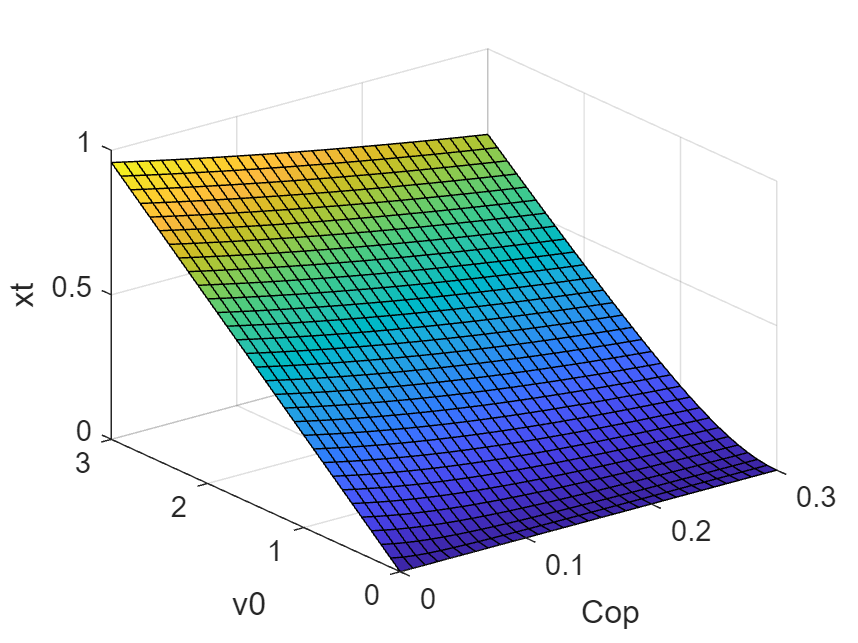

v0 = [0:0.1:3];
Cop = [0:0.01:0.3];
[v0_mesh,Cop_mesh] = meshgrid(v0,Cop);
y0 = 1;
g = 9.81;

xt = -Cop_mesh +1/g*(sqrt((g*Cop_mesh).^2+g*y0*v0_mesh.^2));

surf(Cop_mesh,v0_mesh,xt)
hold on 
% xt2 = v0_mesh*(y0/g)*0.5;
% surf(Cop_mesh,v0_mesh,xt2)

xlabel('Cop');
ylabel('v0');
zlabel('xt')

### Question 2

y_des = 0.9;
y_des_dot = 0;

Fs_des = 0;
Fs = 0;

y0=1;
y0_dot = 0;

y = y0;
y_dot = 0;

e1 = y_des - y;
e1_dot = 0;

t_m= 0;
theta_m=0;
theta_m_dot =0;

theta_m_des = 0;
theta_m_des_dot = 0;


kd1 = 15;
kp1 = 50;

kd2 = 130;
kp2 = 4200;

N = 40.532; %kg m / s^2 N
r = 0.05; % m
Jm = 0.000506; % kg m^2
m = 80; % kg
g = 9.81;% m/s^2
K = 20000; % kNm^-1

timestep = 0.1;
timestep2 = 0.01;


time = 0:timestep:10;
Fs_des_list = zeros(length(time), 1);
t_m_list = zeros(length(time), 1);

time2 = 0:timestep2:timestep;

Fs_list = zeros(length(time), 1);
theta_m_list = zeros(length(time2), 1);

theta_m_state_list = zeros(length(time2), 2);

y_list = zeros(length(time), 1);
y_list(1) = y;
y_state_list = zeros(length(time), 2);
y_state_list(1) = y;

for i=1:length(time) - 1

    index = i;

    e1 = y_des - y;
    e1_dot = -y_dot;

    Fs_des = m*g + m*kd1*e1_dot+m*kp1*e1;
    Fs_des_list(index) = Fs_des;

    for j=1:length(time2)- 1
        index_inner =j;
    
        theta_m_des = (N*Fs_des - N*K*e1)/(K*r);
        
        
        e = theta_m_des - theta_m;
        e_dot = theta_m_des_dot - theta_m_dot;
    
        t_m = Jm*kd2*e_dot+Jm*kp2*e+r*K/N *(e1+r*theta_m/N);
        [theta_m_time, theta_m_state] = ode45(@(t, x) func3(t, x, t_m, e1), [0, timestep2], theta_m_state_list(index_inner, :)');
        theta_m_state_list(index_inner+1, :) = theta_m_state(end, :);
    
        theta_m =theta_m_state(end, 1);
        theta_m_dot =theta_m_state(end, 2);
    
        Fs = K*(e1+(r*theta_m)/N);
        
    end

    t_m_list(index+1) = t_m;

    Fs_list(index+1) = Fs;
    [y_time, y_state] = ode45(@(t, x) func4(t, x, Fs), [0, timestep], y_state_list(index, :)');
    
    y = y_state(end, 1);
    y_dot = y_state(end, 2);
    y_state_list(index+1, :) = y_state(end, :);

    y_list(index+1)=y;

end


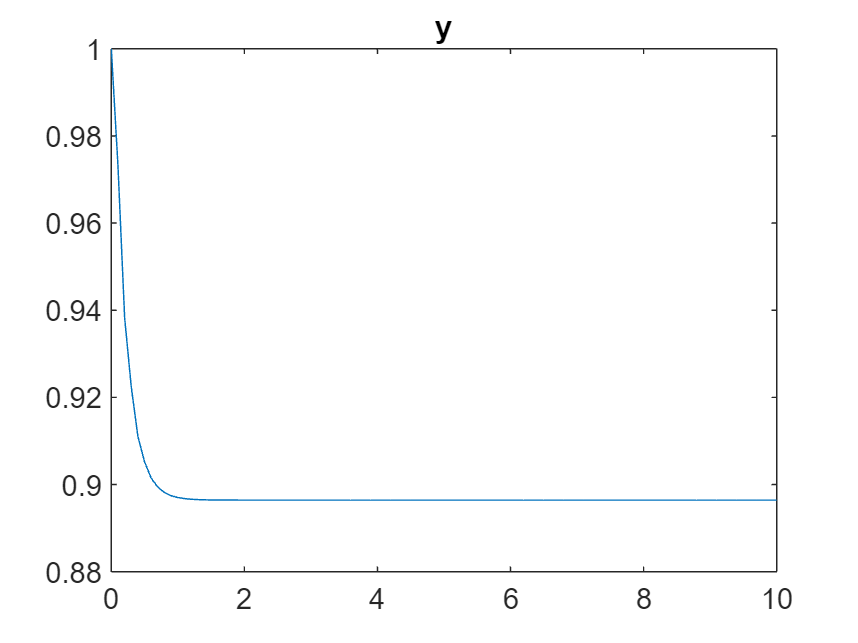

% figure 
% plot(time, Fs_list)
% hold on
% plot(time, Fs_des_list)
% title('Fs')
% legend('Fs', 'Fs-des')
% figure 
% plot(time, Fs_des_list - Fs_list)
% title('Fs-des - Fs')

figure 
plot(time, y_list)
title('y')

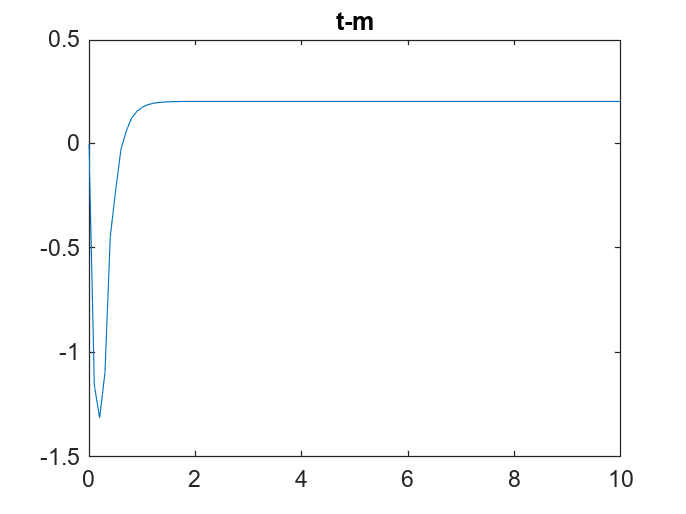

figure 

plot(time, t_m_list)
title('t-m')

function out = func3(t, x, t_m, e1)
    N = 40.532; %kg m / s^2 N
    r = 0.05; % m
    Jm = 0.000506; % kg m^2
    m = 80; % kg
    g = 9.81;% m/s^2
    K = 20000; % kNm^-1

    A = [0 1;
        -(r^2*K)/(N^2*Jm) 0]; % - 
    B=[0;
        t_m/Jm - (r*K*e1)/(N*Jm)]; % -
    out = A*x+B;
end

function out = func4(t, x, Fs)
    N = 40.532; %kg m / s^2 N
    r = 0.05; % m
    Jm = 0.000506; % kg m^2
    m = 80; % kg
    g = 9.81;% m/s^2
    K = 20000; % kNm^-1

    A = [0 1;
        0 0];
    B=[0;
        Fs/m-g];

    out = A*x+B;

end